# EX. 1. 

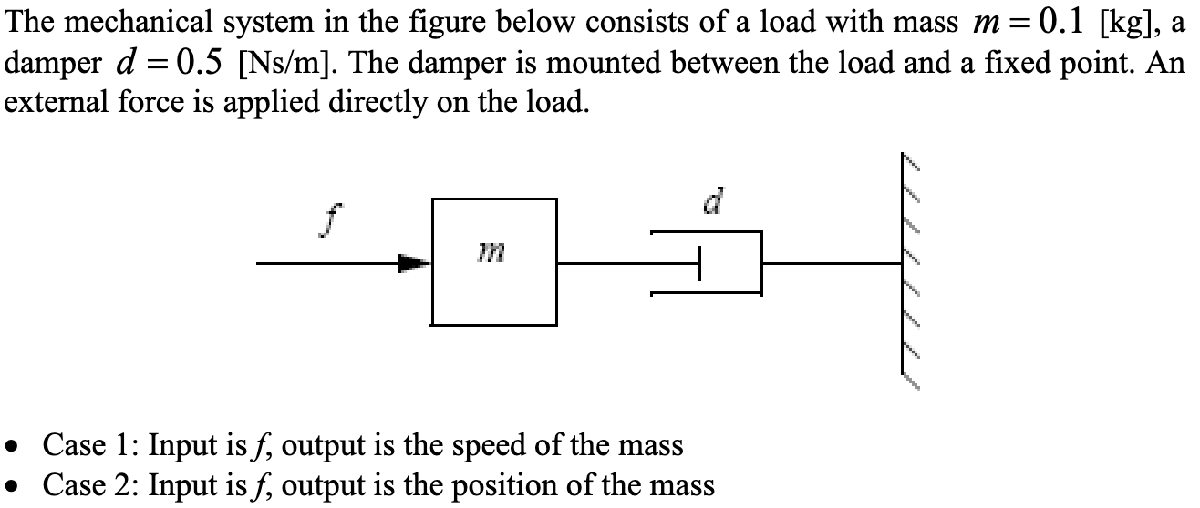

What is the order of the model if the input is f and the output is the speed of the mass?

In this case the system can be described by the formula: $m \dot{v} = f - dv
$ which can be rewritten as: $\dot{v} + \frac{d}{m} v = \frac{f}{m}
$. The highest derivative of the output here is the first derivative and therefore the model is of order 1.

If the output is the position of the mass, what is the order again?

In this case the system can be described by: $m \ddot{x} = f - d \dot{x}
$ which can be rewritten as: $\ddot{x} + \frac{d}{m} \dot{x} = \frac{f}{m}

$. The highest derivative of the output here is the second derivative and therefore the model is of order 2. 

% Basic parameters definition
m = 0.1; % kg
d = 0.5; % Ns/m

The state space models and transfer functions were derived on paper according to the following: 

Case 1: 

State space model:


$$% Define the state-space matrices using brackets
A = [\frac{-d}{m}]\ % A matrix (1-by-1)
B = [\frac{1}{m}]\    % B matrix (1-by-1)
C = [1]\      % C matrix (1-by-1, output = v)
D = [0]\      % D matrix (1-by-1)
$$


Transfer function model: 


$$G_1(s) = \frac{1}{m s + d}
$$


% Derived state space model for case 1:

A = -d/m;

B = 1/m;

% u = F

C1 = 1;

D = 0;

sys1 = ss(A, B, C1, D);

% Derived transfer function model for velocity output

s = tf('s');

G1 = 1 / (m*s + d);

Case 2: 

State space model:


$$A = \left( \matrix{0 & 1 \cr 0 & -\frac{d}{m}} \right), \quad
B = \left( \matrix{0 \cr \frac{1}{m}} \right), \quad
C = \left( \matrix{1 & 0} \right), \quad
D = 0
$$


Transfer function model: 


$$G_2(s) = \frac{1}{m s^2 + d s}

$$


% Derived state space model for case 2:

A = [0, 1; 0, -d/m];

B = [0; 1/m];

C2 = [1, 0];

D = 0;

sys2 = ss(A, B, C2, D);

% Derived transfer function model for position output
G2 = 1 / (m*s^2 + d*s);

The frequency response (bode) for the models is shown below

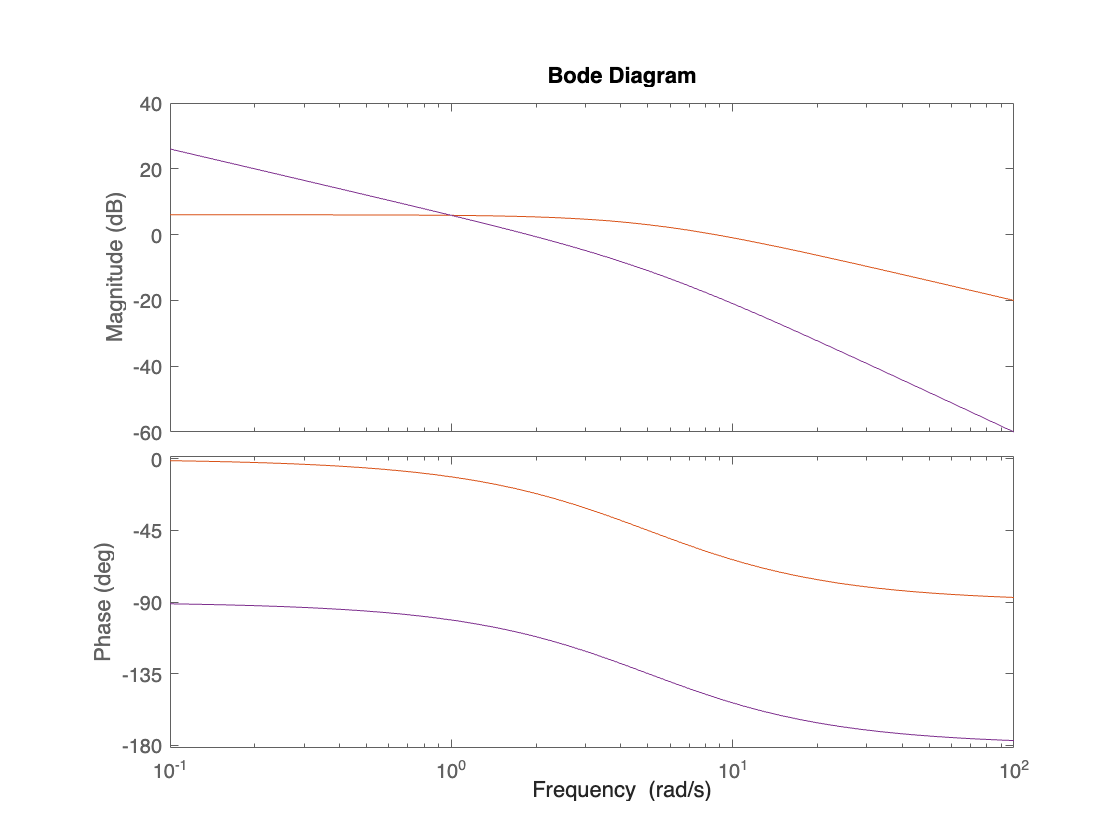

hold on
bode(sys1)

bode(G1)

bode(sys2)

bode(G2)
hold off

The step response of the systems are shown below

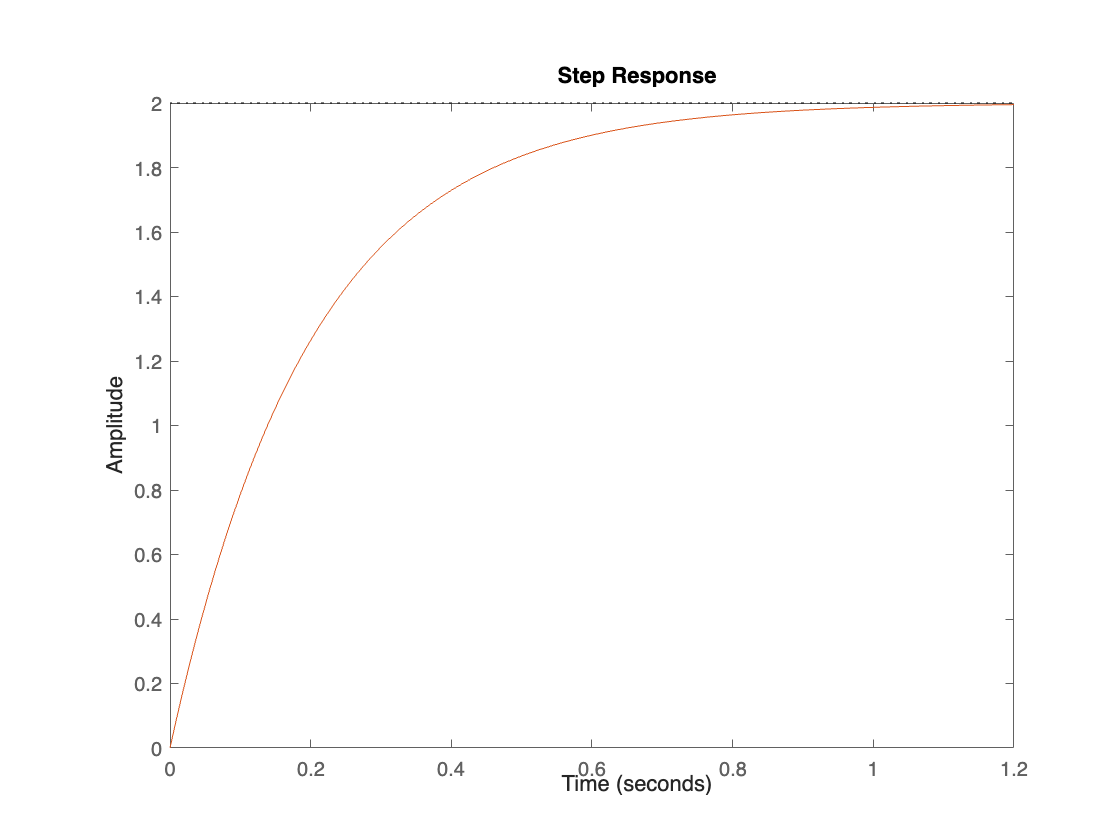


sp =

	resppack.timeplot



% Step response of system with velocity as output
sp = stepplot(sys1, G1)

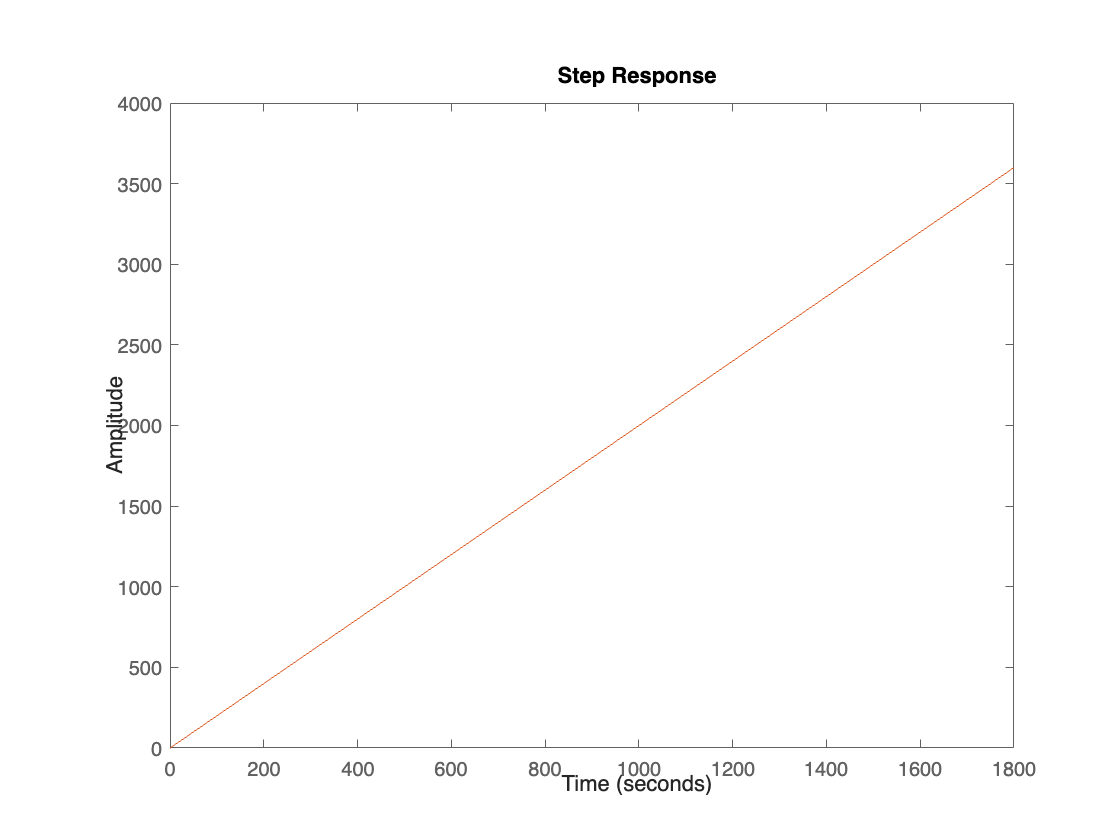


sp2 =

	resppack.timeplot




% Step response of a system with position as output
sp2 = stepplot(sys2, G2)

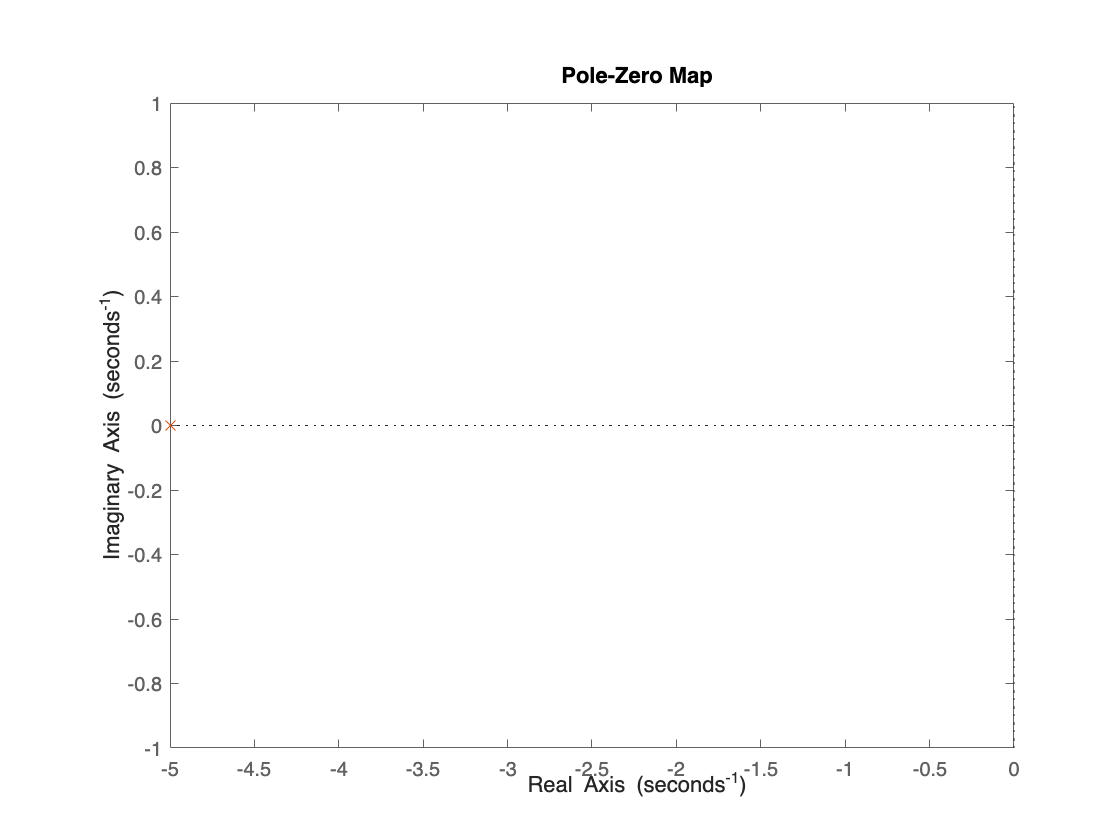


pzp =

	resppack.mpzplot





% Pole-zero plot of system with position as output
pzp = pzplot(sys1, G1)

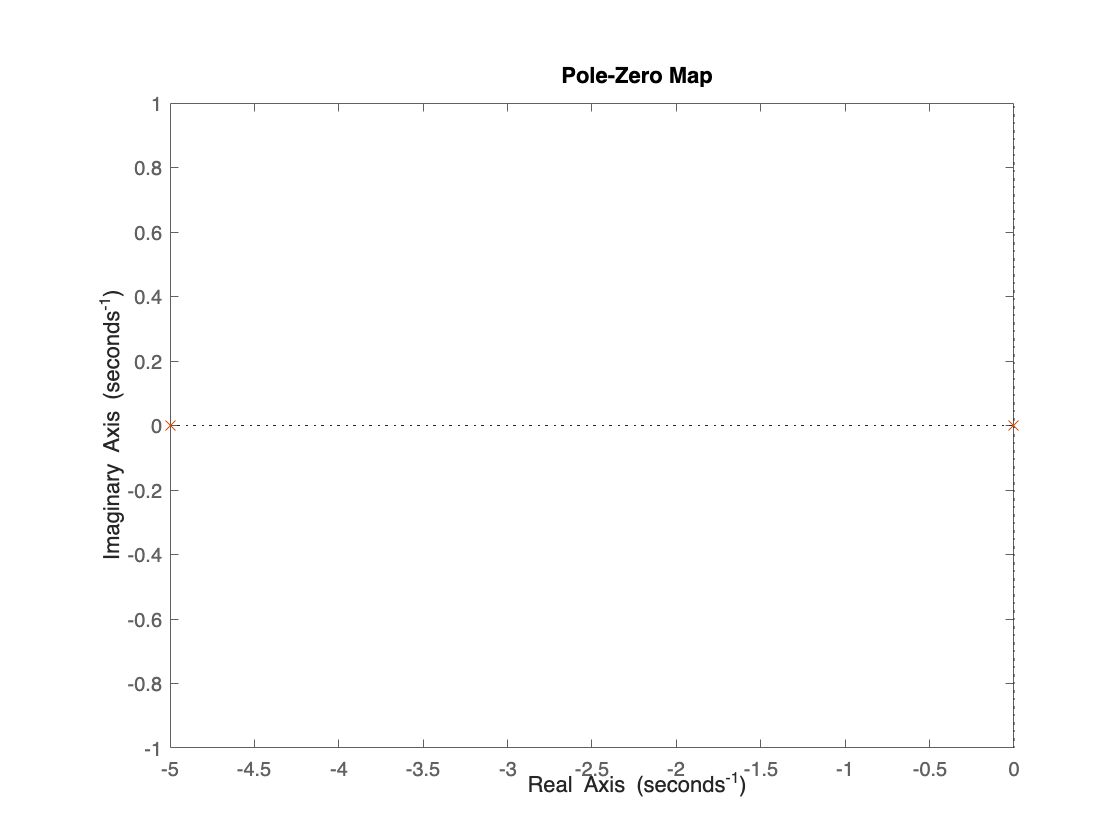


pzp2 =

	resppack.mpzplot




% Pole-zero plot of a system with velocity as output
pzp2 = pzplot(sys2, G2)